DNN

% housekeeping 

% add folder with helper function tp to path
function_folder = fullfile(pwd, 'functions', filesep);
addpath(genpath(function_folder))

d = struct;
cfg = struct;

% get subject numbers
cfg.exp_num = 1;
if cfg.exp_num == 1
    cfg.subNums = 4:37;
elseif cfg.exp_num == 2
    cfg.subNums = [102:108, 110:136];
end
cfg.n = length(cfg.subNums);

% get subject info
cfg = extractParticipantInfo(cfg);

Subjects: 34
Mean age: 28.56 (SD = 5.05)
Gender: 23 female, 11 male, 0 other


cfg = struct with fields:
    exp_num: 1
    subNums: [4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37]
          n: 34
     sample: [1×1 struct]



% other standard configurations
cfg.categories = {'bathroom', 'kitchen'};
cfg.colormaps = load('white_zero_colormap.mat');
cfg.FontName = 'Helvetica';
cfg.FontSize = 15;


% load images and get DNN representation
images = load_images(cfg);

Loaded image: 004_bath1_3D.png
Loaded image: 004_bath2_3D.png
Loaded image: 004_bath3_3D.png
Loaded image: 005_bath1_3D.png
Loaded image: 005_bath2_3D.png
Loaded image: 005_bath3_3D.png
Loaded image: 006_bath1_3D.png
Loaded image: 006_bath2_3D.png
Loaded image: 006_bath3_3D.png
Loaded image: 007_bath1_3D.png
Loaded image: 007_bath2_3D.png
Loaded image: 007_bath3_3D.png
Loaded image: 008_bath1_3D.png
Loaded image: 008_bath2_3D.png
Loaded image: 008_bath3_3D.png
Loaded image: 009_bath1_3D.png
Loaded image: 009_bath2_3D.png
Loaded image: 009_bath3_3D.png
Loaded image: 010_bath1_3D.png
Loaded image: 010_bath2_3D.png
Loaded image: 010_bath3_3D.png
Loaded image: 011_bath1_3D.png
Loaded image: 011_bath2_3D.png
Loaded image: 011_bath3_3D.png
Loaded image: 012_bath1_3D.png
Loaded image: 012_bath2_3D.png
Loaded image: 012_bath3_3D.png
Loaded image: 013_bath1_3D.png
Loaded image: 013_bath2_3D.png
Loaded image: 013_bath3_3D.png
Loaded image: 014_bath1_3D.png
Loaded image: 014_bath2_3D.png
Loaded i

analysis typical - layer #1 - category: bathroom
Length of labels do not match matrix dimensions


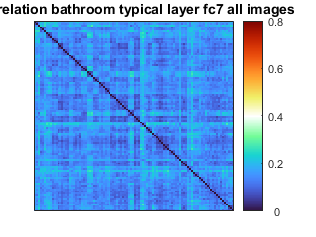

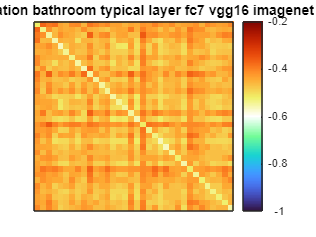

analysis typical - layer #1 - category: kitchen
Length of labels do not match matrix dimensions


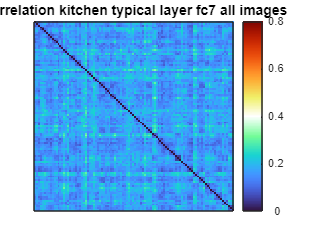

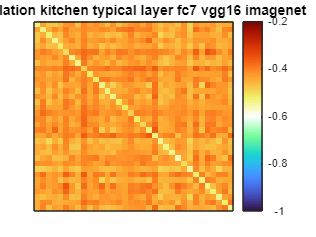


% typical images 
cfg.analysis_name = 'typical';
[d, cfg] = get_dnn_layer_similarity(d, images, cfg);

analysis control - layer #1 - category: bathroom
Length of labels do not match matrix dimensions


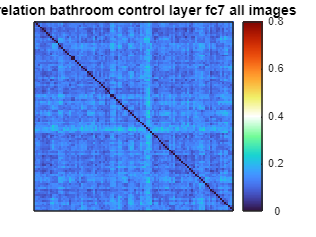

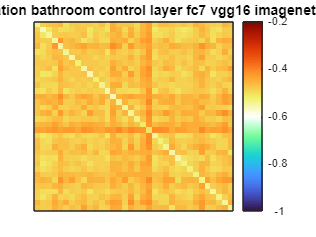

analysis control - layer #1 - category: kitchen
Length of labels do not match matrix dimensions


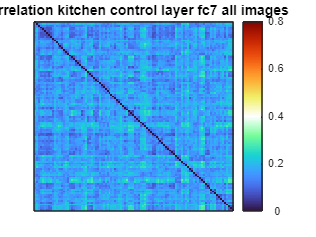

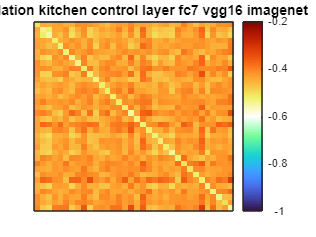


% control images 
cfg.analysis_name = 'control';
[d, cfg] = get_dnn_layer_similarity(d, images, cfg);

Gaze

%a_preprocessing(cfg)
%b_detFix(cfg)
%c_showFix
%d_AOIfix(cfg)

e_getGazePatterns(cfg);

Subject 004 already exists
Subject 005 already exists
Subject 006 already exists
Subject 007 already exists
Subject 008 already exists
Subject 009 already exists
Subject 010 already exists
Subject 011 already exists
Subject 012 already exists
Subject 013 already exists
Subject 014 already exists
Subject 015 already exists
Subject 016 already exists
Subject 017 already exists
Subject 018 already exists
Subject 019 already exists
Subject 020 already exists
Subject 021 already exists
Subject 022 already exists
Subject 023 already exists
Subject 024 already exists
Subject 025 already exists
Subject 026 already exists
Subject 027 already exists
Subject 028 already exists
Subject 029 already exists
Subject 030 already exists
Subject 031 already exists
Subject 032 already exists
Subject 033 already exists
Subject 034 already exists
Subject 035 already exists
Subject 036 already exists
Subject 037 already exists
Subject 004 already exists
Subject 005 already exists
Subject 006 already exists
S

e_getGazePatterns_firstFix(cfg);

Subject 004 already exists
Subject 005 already exists
Subject 006 already exists
Subject 007 already exists
Subject 008 already exists
Subject 009 already exists
Subject 010 already exists
Subject 011 already exists
Subject 012 already exists
Subject 013 already exists
Subject 014 already exists
Subject 015 already exists
Subject 016 already exists
Subject 017 already exists
Subject 018 already exists
Subject 019 already exists
Subject 020 already exists
Subject 021 already exists
Subject 022 already exists
Subject 023 already exists
Subject 024 already exists
Subject 025 already exists
Subject 026 already exists
Subject 027 already exists
Subject 028 already exists
Subject 029 already exists
Subject 030 already exists
Subject 031 already exists
Subject 032 already exists
Subject 033 already exists
Subject 034 already exists
Subject 035 already exists
Subject 036 already exists
Subject 037 already exists
Subject 004 already exists
Subject 005 already exists
Subject 006 already exists
S


cfg.variables_of_interest = {'ObjectFixCount',...
    'ObjectDwellsCate', 'ObjectDwellsCateEven', 'ObjectDwellsCateOdd',...
    'ObjectsCate_firstFix', 'ObjectsCate_firstFixEven', 'ObjectsCate_firstFixOdd',...
    'IndividualObjectDwells', 'IndividualObjects_firstFix',...
    'ObjectCatePrio', 'ObjectCatePrioOdd', 'ObjectCatePrioEven'};
 d = makeGDM(d, cfg);
 d = regressOutMean(d, cfg);


Get inter-subject correlation

Plotting and saving inter-subject RDM for task:ObjectFixCount and bathroom


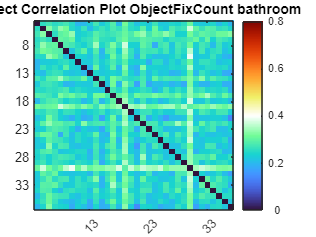

Plotting and saving inter-subject RDM for task:ObjectDwellsCate and bathroom


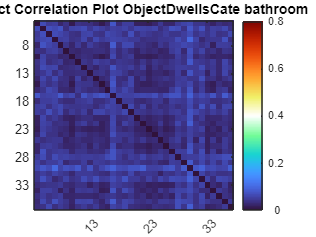

Plotting and saving inter-subject RDM for task:ObjectDwellsCateEven and bathroom


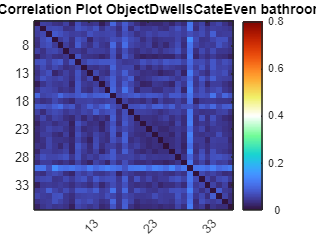

Plotting and saving inter-subject RDM for task:ObjectDwellsCateOdd and bathroom


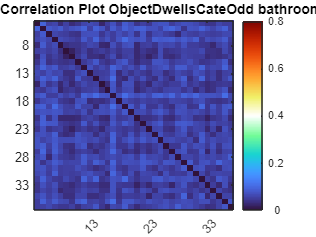

Plotting and saving inter-subject RDM for task:ObjectsCate_firstFix and bathroom


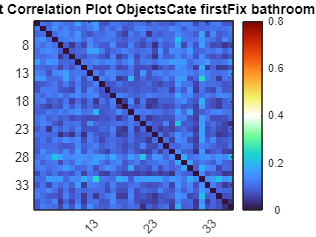

Plotting and saving inter-subject RDM for task:ObjectsCate_firstFixEven and bathroom


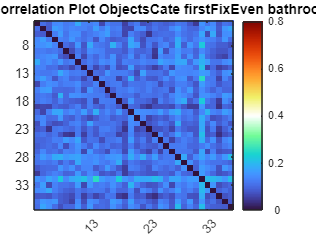

Plotting and saving inter-subject RDM for task:ObjectsCate_firstFixOdd and bathroom


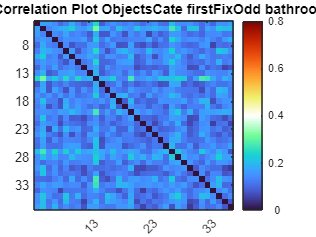

Plotting and saving inter-subject RDM for task:IndividualObjectDwells and bathroom


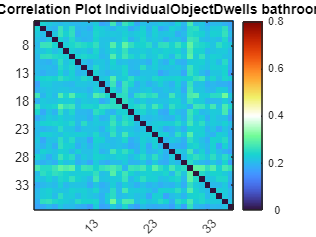

Plotting and saving inter-subject RDM for task:IndividualObjects_firstFix and bathroom


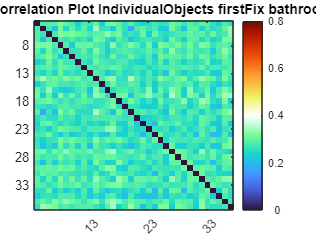

Plotting and saving inter-subject RDM for task:ObjectCatePrio and bathroom


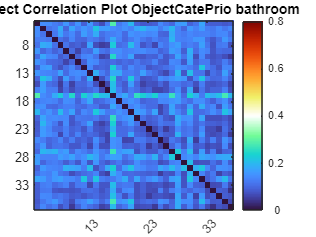

Plotting and saving inter-subject RDM for task:ObjectCatePrioOdd and bathroom


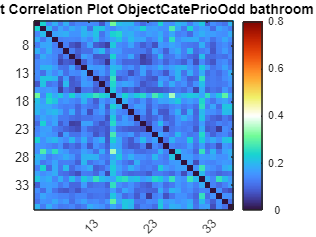

Plotting and saving inter-subject RDM for task:ObjectCatePrioEven and bathroom


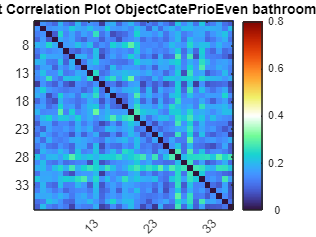

Plotting and saving inter-subject RDM for task:ObjectFixCount and kitchen


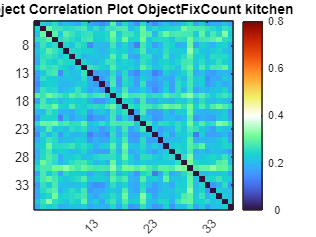

Plotting and saving inter-subject RDM for task:ObjectDwellsCate and kitchen


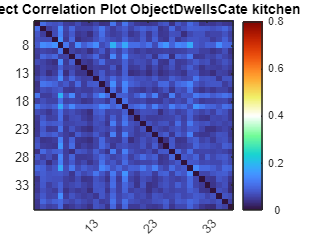

Plotting and saving inter-subject RDM for task:ObjectDwellsCateEven and kitchen


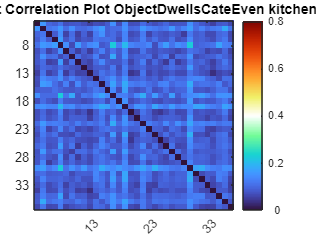

Plotting and saving inter-subject RDM for task:ObjectDwellsCateOdd and kitchen


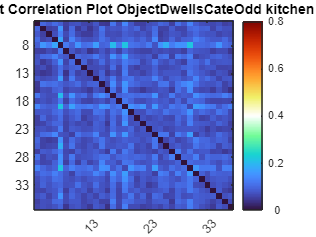

Plotting and saving inter-subject RDM for task:ObjectsCate_firstFix and kitchen


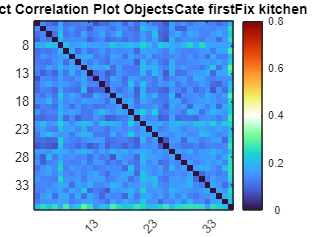

Plotting and saving inter-subject RDM for task:ObjectsCate_firstFixEven and kitchen


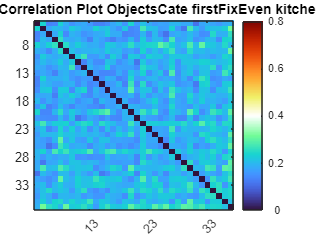

Plotting and saving inter-subject RDM for task:ObjectsCate_firstFixOdd and kitchen


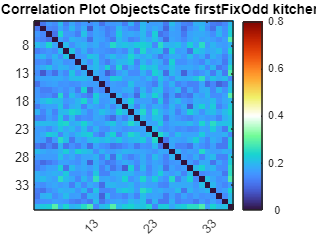

Plotting and saving inter-subject RDM for task:IndividualObjectDwells and kitchen


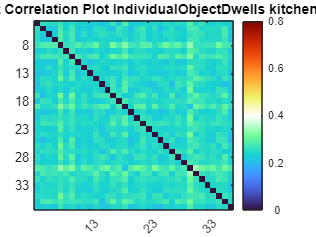

Plotting and saving inter-subject RDM for task:IndividualObjects_firstFix and kitchen


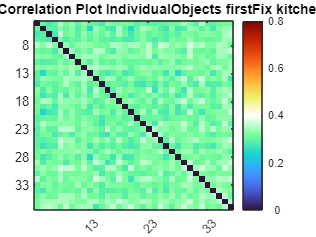

Plotting and saving inter-subject RDM for task:ObjectCatePrio and kitchen


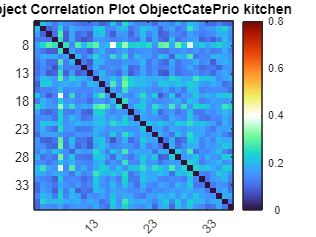

Plotting and saving inter-subject RDM for task:ObjectCatePrioOdd and kitchen


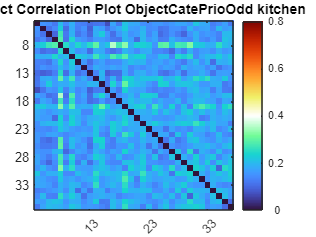

Plotting and saving inter-subject RDM for task:ObjectCatePrioEven and kitchen


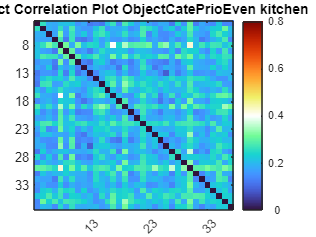

Compare categories


cfg.regressOutMean = false;
d = intersub_cor(d, cfg);

Get gaze distance

d = getGazeDist(d, cfg);

Processing trial 1 with image sun_aaznyvntjefttmaz.jpg
Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 10).
Processing trial 2 with image sun_abntrinbqbsqoowj.jpg
Processing trial 3 with image sun_aapitsgbtktqubfy.jpg
Processing trial 4 with image sun_auetjleugthejgoc.jpg
Processing trial 5 with image sun_azqlhsjgbwpcseew.jpg
Processing trial 6 with image sun_alvdofgavhiiyosk.jpg
Processing trial 7 with image sun_aazqzpomyylceich.jpg
Processing trial 8 with image sun_ajrwezxmmjejxsbt.jpg
Processing trial 9 with image sun_aglpqkbwvbofhrgt.jpg
Processing trial 10 with image sun_azgmgniivgpqrqvu.jpg
Processing trial 11 with image sun_aleqenyvunhactkl.jpg
Processing trial 12 with image sun_azqyogdvyhahyram.jpg
Processing trial 13 with image sun_agldadusrezhmyva.jpg
Processing trial 14 with image sun_ajlxdvfhywnxqswk.jpg
Processing trial 15 with image sun_ahrhvpdhoamfdhpf.jpg
Processing trial 16 with image sun_anecxlyzpkjfxrg

Split half correlation

% split half correlation
cfg.regressOutMean = false;
% cfg.variables_of_interest = {'GazeDist', 'ObjectFixCount',...
%     'ObjectDwellsCate', 'ObjectsCate_firstFix',...
%     'IndividualObjectDwells', 'IndividualObjects_firstFix',...
%     'ObjectCatePrio'};
cfg.variables_of_interest = {'GazeDist', 'ObjectFixCount',...
    'ObjectDwellsCate', 'ObjectCatePrio'};
cfg.correlation_type = 'pearson';
cfg.permutation_test = true;
cfg.n_permutations = 10000;
cfg.permutation_type = 'row_col_shuffle_ref';
d = getSpliHalfReliability(d, cfg);

 
Fixation count
r: 0.36407, p = 5.033e-19
10% of permutations of is done
20% of permutations of is done
30% of permutations of is done
40% of permutations of is done
50% of permutations of is done
60% of permutations of is done
70% of permutations of is done
80% of permutations of is done
90% of permutations of is done
100% of permutations of is done
 
Category dwell time
r: 0.25434, p = 9.8697e-10
10% of permutations of is done
20% of permutations of is done
30% of permutations of is done
40% of permutations of is done
50% of permutations of is done
60% of permutations of is done
70% of permutations of is done
80% of permutations of is done
90% of permutations of is done
100% of permutations of is done
 
Category first fixation count
r: 0.23708, p = 1.315e-08
10% of permutations of is done
20% of permutations of is done
30% of permutations of is done
40% of permutations of is done
50% of permutations of is done
60% of permutations of is done
70% of permutations of is done
80% of perm

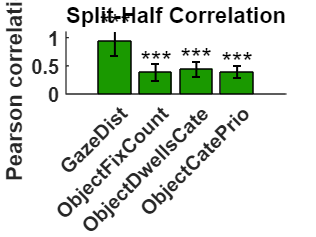

plotSpliHalfReliability(d, cfg);

Compare them

 Start evaluating predictor RDMs
Predictor RDMs evaluated
10% of permutations of GazeDist bathroom is done
20% of permutations of GazeDist bathroom is done
30% of permutations of GazeDist bathroom is done
40% of permutations of GazeDist bathroom is done
50% of permutations of GazeDist bathroom is done
60% of permutations of GazeDist bathroom is done
70% of permutations of GazeDist bathroom is done
80% of permutations of GazeDist bathroom is done
90% of permutations of GazeDist bathroom is done
100% of permutations of GazeDist bathroom is done
Compare inter-subject RDM of GazeDist with partial correaltion of predictor RDMs - bathroom
 Start evaluating predictor RDMs
Predictor RDMs evaluated
10% of permutations of GazeDist kitchen is done
20% of permutations of GazeDist kitchen is done
30% of permutations of GazeDist kitchen is done
40% of permutations of GazeDist kitchen is done
50% of permutations of GazeDist kitchen is done
60% of permutations of GazeDist kitchen is done
70% of permut

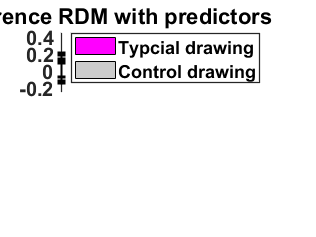

% preparation
cfg.partial_cor = true;
cfg.plot_rdm = false;
cfg.RDM_to_partial_out = {'Typical Images vgg16_imagenet Late','Control Images vgg16_imagenet Late'};
cfg.predictor_RDMs = {'typical_late', 'control_late'};
cfg.variables_of_interest = {'GazeDist', 'ObjectFixCount',...
    'ObjectDwellsCate', 'ObjectCatePrio'};
cfg.dnns = {'vgg16_imagenet'};
cfg.plot_type = 'bar';
cfg.show_single_cate = false;
cfg.permutation_test = true;
cfg.n_permutations = 10000;
cfg.permutation_type = 'row_col_shuffle_ref';
cfg.ylim = [-.25, .45];
cfg.partial_correlation_type = 'pearson';
cfg.fdr_correction = false;

d = compare_task_RDMs_to_predictor_RDMs(d, cfg);

Compare drawing oder and fixation order

cfg.partialCorr = true; % control for object size in stimuli
d = evaluateDrawingOrder(d, cfg)


Compare gazeDist in bined time windows

% preparation
cfg.partial_cor = true;
cfg.plot_rdm = false;
cfg.RDM_to_partial_out = {'Typical Images vgg16_imagenet Late','Control Images vgg16_imagenet Late'};
cfg.predictor_RDMs = {'typical_late', 'control_late'};
cfg.variables_of_interest = {'GazeDist'};
cfg.dnns = {'vgg16_imagenet'};
cfg.show_single_cate = false;
cfg.ylim = [-.21, .41];
cfg.partial_correlation_type = 'pearson';

d = compare_tp_RDMs_to_predictor_RDMs(d, cfg);

Get memory task performance

if cfg.exp_num == 2
    d = getAccuracyMemoryTask(cfg, d)
end
